**Set Up**

p_array = round(normrnd(.55,.1,1,1000),3);
b_array = 5*ones(1,1000);

prob_values = (1:999)/1000;
pool_values = zeros(1,999);
for ii = 1:length(p_array)
    pool_values( round(p_array(ii)*1000) ) = pool_values( round(p_array(ii)*1000) ) + b_array(ii);
end

empty_slot = (pool_values == 0);
prob_values = prob_values(~empty_slot);
pool_values = pool_values(~empty_slot);
 

**Test with Fourier Sine Series**

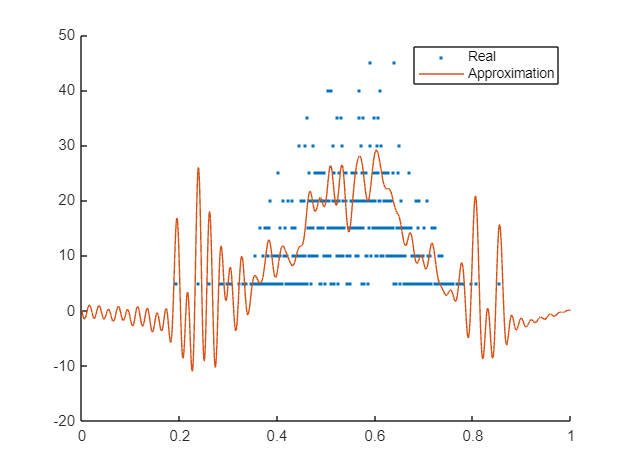

N = 100;

A = zeros(1,N);

for n = 1:N
    A(n) = trapz(prob_values,pool_values.*sin(n*pi*prob_values))/trapz(prob_values,sin(n*pi*prob_values).^2);
end

figure
hold on
plot(prob_values,pool_values,'LineStyle','none','Marker','.')

x_mesh = 0:.0001:1;
approx_matrix = zeros(length(x_mesh),N);
for ii = 1:length(x_mesh)
    for n = 1:N
        approx_matrix(ii,n) = sin(n*pi*x_mesh(ii));
    end
end
approx_vector = approx_matrix*A';
plot(x_mesh,approx_vector)

legend({'Real','Approximation'})

**Approximations**

% Fourier Sine Series
    % Goal: Error vs. Number of Terms
    % Error is sup{|f(x)-F_n(x)| : x in prob_values}
